# Figure 5D left 

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A050_data.mat'],'S','settings','allIF');
conditions = settings.conditions

conditions = 20×5 cell array
    {'TAK DMSO'        }    {[2 3 4]}    {[2]}    {[1]}    {[37]}
    {'DMSO DMSO'       }    {[5 6 7]}    {[2]}    {[1]}    {[37]}
    {'TAK DOX'         }    {[2 3 4]}    {[3]}    {[1]}    {[37]}
    {'DMSO DOX'        }    {[5 6 7]}    {[3]}    {[1]}    {[37]}
    {'TAK 1i 20uM'     }    {[2 3 4]}    {[4]}    {[1]}    {[37]}
    {'DMSO 1i 20uM'    }    {[5 6 7]}    {[4]}    {[1]}    {[37]}
    {'TAK 1i 10uM'     }    {[2 3 4]}    {[5]}    {[1]}    {[37]}
    {'DMSO 1i 10uM'    }    {[5 6 7]}    {[5]}    {[1]}    {[37]}
    {'TAK 2i 1uM'      }    {[2 3 4]}    {[6]}    {[1]}    {[37]}
    {'DMSO 2i 1uM'     }    {[5 6 7]}    {[6]}    {[1]}    {[37]}
    {'TAK 1+2i 10+1uM' }    {[2 3 4]}    {[7]}    {[1]}    {[37]}
    {'DMSO 1+2i 10+1uM'}    {[5 6 7]}    {[7]}    {[1]}    {[37]}
    {'TAK 1+2i 20+1uM' }    {[2 3 4]}    {[8]}    {[1]}    {[37]}
    {'DMSO 1+2i 20+1uM'}    {[5 6 7]}    {[8]}    {[1]}    {[37]}
    {'TAK 4/6i'        }    {[2 3 4]}    {[9]} 



framesPerHr = 60/12;
 frameDrugAdded =37;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};
% 
for i = 1:length(S)
    S(i).frameDrugAdded = conditions{i,5};
    S(i).POI_realtime = S(i).POI/framesPerHr;
    S(i).POI_drug_time = ( S(i).frameDrugAdded - S(i).POI)/framesPerHr;
   S(i).drug_time = S(i).frameDrugAdded/framesPerHr;
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,2)),1);
    apcGateAll = false(length(dat.POI(:,1)),1); 
     crlGate = false(length(dat.POI(:,3)),1);

    for n = 1:length(dat.POI(:,1))
       if dat.POI(n,1) + round(.5*framesPerHr) <= numFrames & dat.POI(n,1) > 1 * framesPerHr
            apcExpressGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(.5*framesPerHr)) < .1 & ...
               dat.apcNormM(n,dat.POI(n,1) - 1 * framesPerHr) > .5 ;
       end
       if dat.POI(n,1) + round(.5*framesPerHr) <= numFrames & dat.POI(n,1) > 1 * framesPerHr
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(.5*framesPerHr)) < .1 & ...
               dat.apcNormM(n,dat.POI(n,1) - 1 * framesPerHr) > .5 ;
       end

        if dat.POI(n,2) + round(5*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNuc(n,dat.POI(n,2) + round(5*framesPerHr)) < 400;
            apcGateAll(n) = true;
        end
       if dat.POI(n,1) > 1 * framesPerHr
            crlGate(n) = dat.crlNuc(n,dat.POI(n,1) - 1 * framesPerHr) >  100;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
        S(i).apcGate = apcGate;
S(i).apcGateAll = apcGateAll;

   S(i).crlGate = crlGate;


end

CRL activation post mitosis CDK2i + TAK

conds=[1 9 7];
timeGate = [0 drug_time];
cols =  [1 .4 .2;.7 .9 .1;1 .2 .4;0 .1 1;.6 .1 .5;.7 .7 .2; 1 .5 .2; 0 .4 .6; .855 .384 1;0 0 1];
linetype = {'-','-','--','--'};

figure('unit','inches','position',[0 0 4 4])
nexttile
hold on
POI_align = 1;
POI_cal = 3;
data_out = [];
frames_out = [];

for i=1:length(conds)
    data = S(conds(i));
      inds = ~isnan(S(conds(i)).POI(:,POI_align)) & S(conds(i)).goodCdk& ...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & (S(conds(i)).POI_realtime(:,3) > drug_time +1| isnan(S(conds(i)).POI(:,3)) );

    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

   y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 
    
   plot(x,f, 'Color',cols(i,:),'linestyle',linetype(i),'LineWidth',1.5);
 
    sum(inds)
end

ans = 1419

ans = 1383

ans = 1311

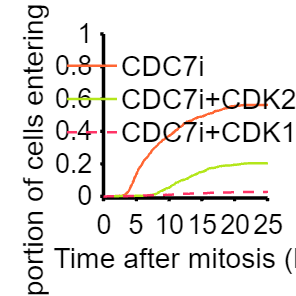



axis square
legend('CDC7i','CDC7i+CDK2i','CDC7i+CDK1i','Box','off','Location','north','FontSize',17);
xlim([0 25]); 
xticks(0:5:25)
ylim([-.01 1]);
yticks(0:.2:1)
xtickangle(0)
xlabel('Time after mitosis (h)','FontSize',17)
ylabel('Proportion of cells entering S phase','FontSize',17)
hold on

 % print_pdf(['fig_5D_left.pdf'])